fs=20;
N_samples=2000;
f_max=0.3;

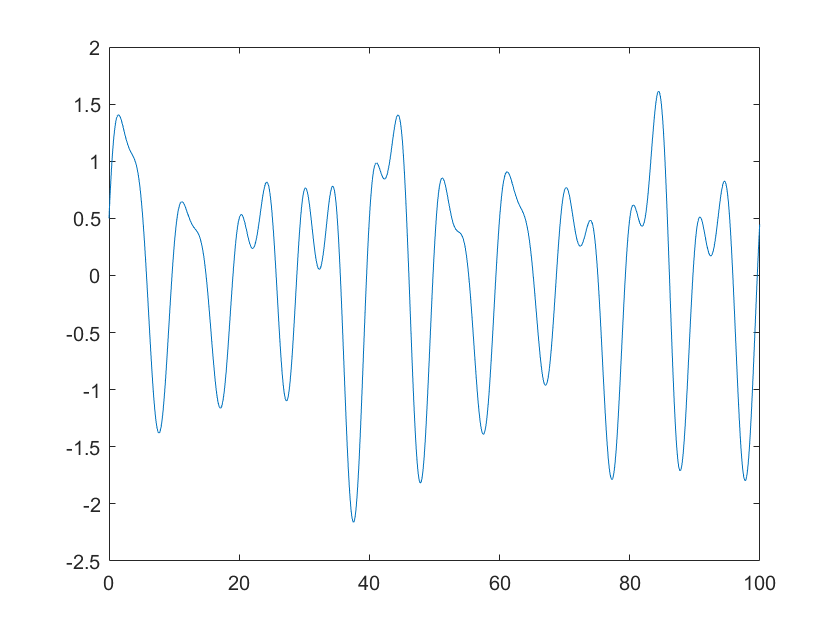

t= (0:N_samples-1)/fs;
a=sin(2*pi*t*0.1)+0.5*cos(2*pi*t*0.2)+0.25*sin(2*pi*t*0.05)+0.25*sin(2*pi*t*0.075)+0.25*sin(2*pi*t*0.12)+0.25*sin(2*pi*t*0.18);
plot(t,a)

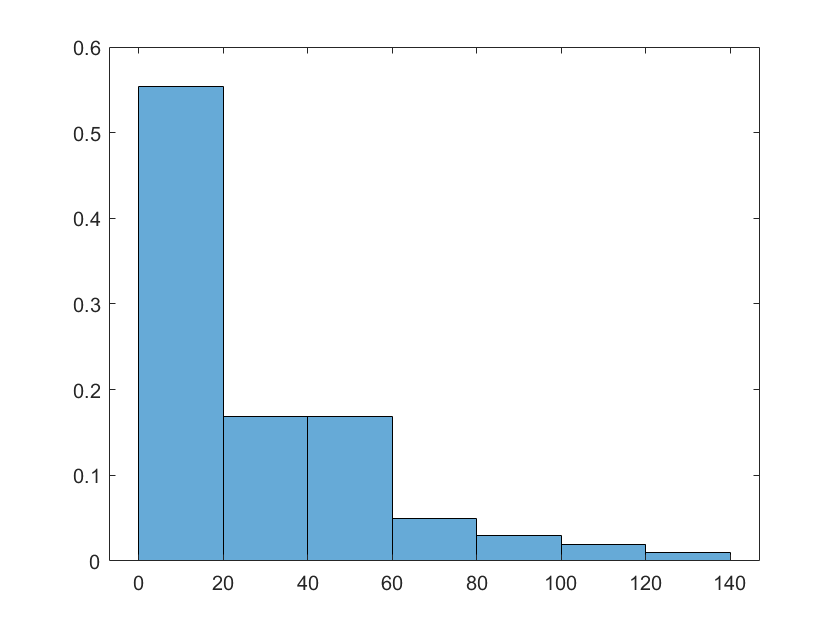

hhe = 0.1862

hhe=hilbert_huang_entropy(a,fs,f_max)

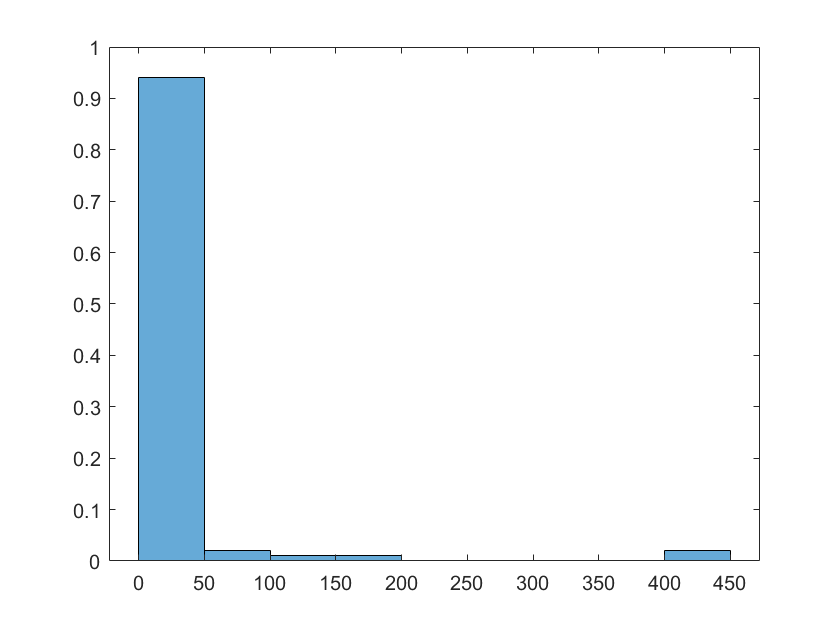

hhe = 0.0338


t= (0:N_samples-1)/fs;
a=sin(2*pi*t*0.1)+0.5*cos(2*pi*t*0.2);
hhe=hilbert_huang_entropy(a,fs,f_max)


t= (0:N_samples-1)/fs;
a=sin(2*pi*t*0.1)

a =          0    0.0314    0.0628    0.0941    0.1253    0.1564    0.1874    0.2181    0.2487    0.2790    0.3090    0.3387    0.3681    0.3971    0.4258    0.4540    0.4818    0.5090    0.5358    0.5621    0.5878    0.6129    0.6374    0.6613    0.6845    0.7071    0.7290    0.7501    0.7705    0.7902    0.8090    0.8271    0.8443    0.8607    0.8763    0.8910    0.9048    0.9178    0.9298    0.9409    0.9511    0.9603    0.9686    0.9759    0.9823    0.9877    0.9921    0.9956    0.9980    0.9995


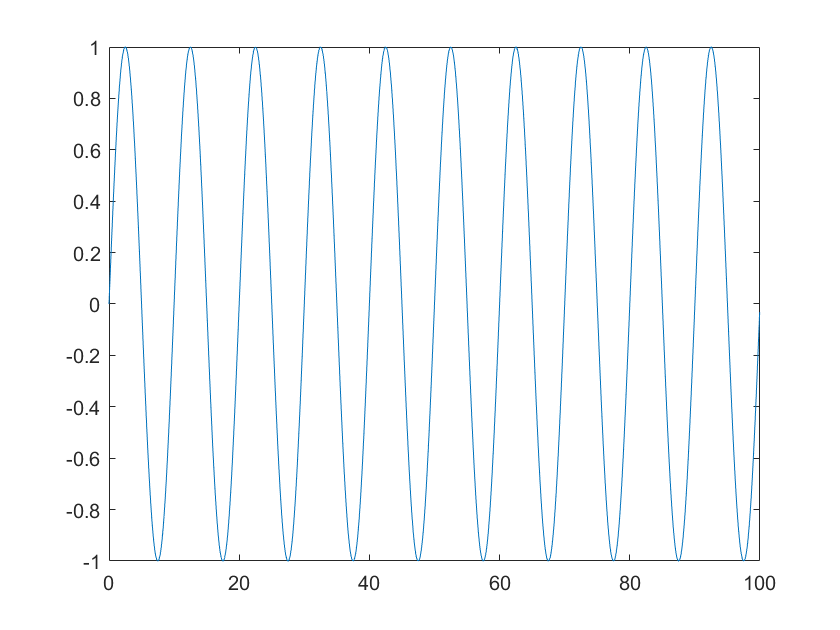

plot(t,a)

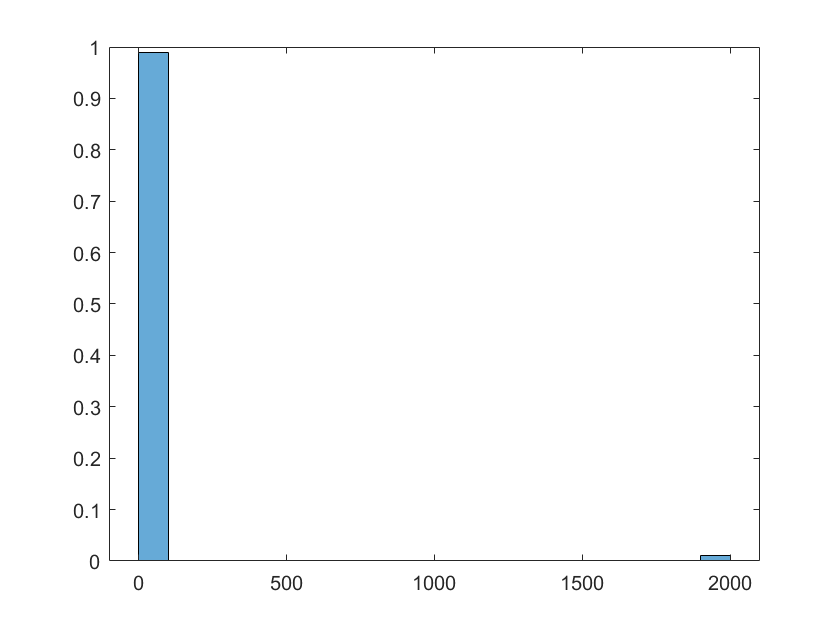

hhe = 0.0028

hhe=hilbert_huang_entropy(a,fs,f_max)

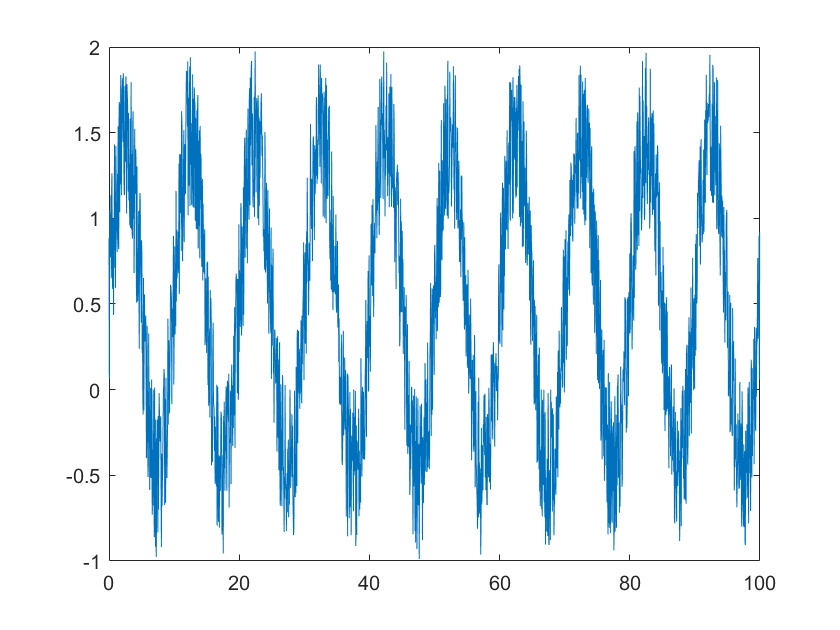


t= (0:N_samples-1)/fs;
a=sin(2*pi*t*0.1)+rand(size(t));
plot(t,a)

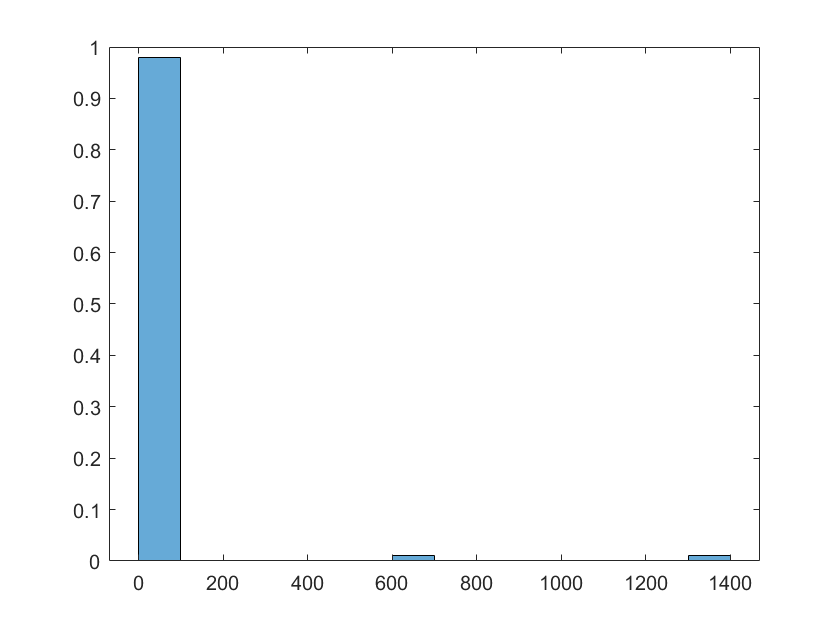

hhe = 0.0079

hhe=hilbert_huang_entropy(a,fs,fs/2-1)


t= (0:N_samples-1)/fs;
a=rand(size(t))

a =     0.1324    0.1209    0.9137    0.9484    0.6644    0.5607    0.1572    0.6966    0.4122    0.5842    0.9885    0.0176    0.6218    0.1406    0.8036    0.0815    0.3299    0.2569    0.0740    0.2724    0.5099    0.3983    0.0046    0.1288    0.9184    0.2748    0.7519    0.9785    0.5733    0.4794    0.1188    0.5505    0.6999    0.7074    0.2420    0.4913    0.5533    0.4407    0.6683    0.9341    0.6522    0.1672    0.2400    0.3853    0.3207    0.5777    0.9872    0.2684    0.5781    0.2921


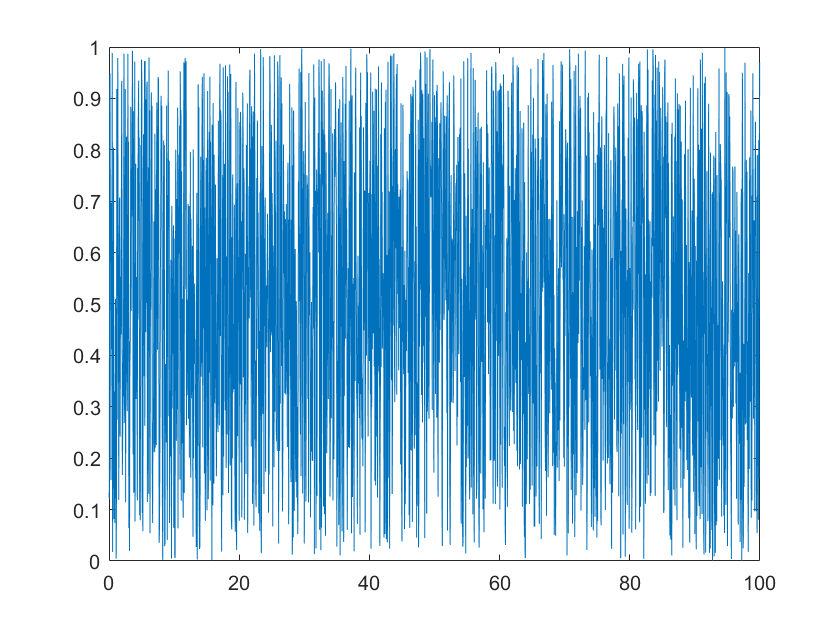

plot(t,a)

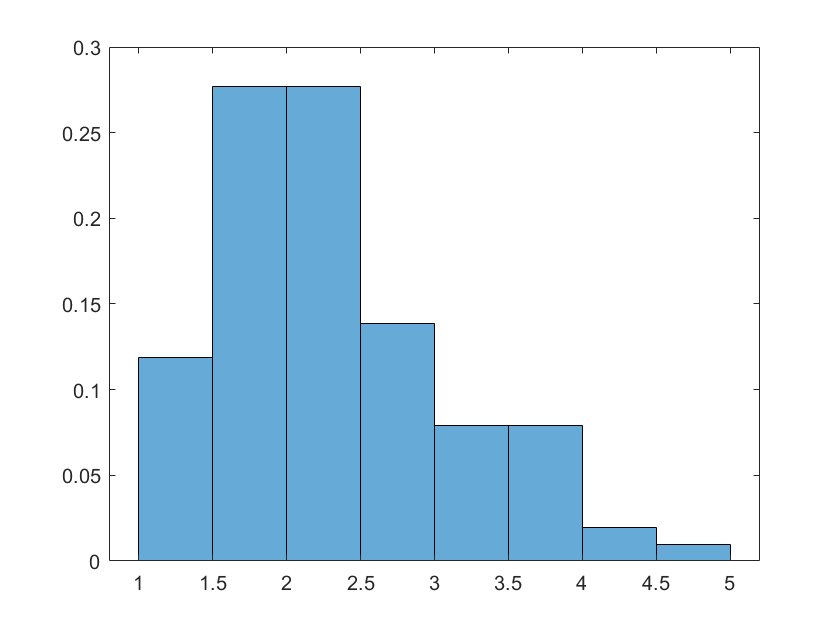

hhe = 0.2204

hhe=hilbert_huang_entropy(a,fs,8)

function [hhe]=hilbert_huang_entropy(Signal,fs,f_max)%%https://github.com/jlpscampos/Ensemble_EMD_significance_test
    %addpath(genpath("D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\MATLAB-COde\Ensemble_EMD_significance_test-main"))
    %EEMD=EMD_timeseries(t,a,'pchip')
    %plot_sign(EEMD, "ic","None")
    % %rmpath(genpath("D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\MATLAB-COde\Ensemble_EMD_significance_test-main"))
    
    [imf,residual,info] = emd(Signal,'Interpolation','pchip');
    %emd(Signal)
    [hs,f,t,imfinsf,imfinse] =hht(imf,fs,'FrequencyLimits',[0 ,f_max]);
    %hht(imf,fs,'FrequencyLimits',[0 ,f_max])
    hf=sum(full(hs),2);
    n_bins=round(find_no_of_bins(hf)*1.2);
    figure()
    h_object=histogram(hf,"Normalization","probability");
    n_bins=h_object.NumBins;
    figure()
    hhe=0;
    for i=1:n_bins
        if(h_object.Values(i)==0)
            continue
        end
       hhe=hhe-h_object.Values(i)*log(h_object.Values(i));
    end
    hhe=hhe/n_bins;
end
function n=find_no_of_bins(X)
    %no of bins calulated using the 2 
    
    h=2*iqr(X)/(length(X))^(1/3);
    n=round((max(X)-min(X))/h);
    
    return
end